clear; clc; close all; mpt_init; yalmip('clear'); 

MPT searches for solvers on the path ...
 
 LINPROG ............................................ linprog.m 
 QUADPROG .......................................... quadprog.m 
 GLPK .................................................. glpkcc 
 CDD ................................................... cddmex 
 MOSEK ............................................... mosekopt 
 LCP ...................................................... lcp 
 SEDUMI .............................................. sedumi.m 
 PLCP .............................................. mpt_plcp.m 
 MPQP .............................................. mpt_mpqp.m 
 MPLP .............................................. mpt_mplp.m 
 ENUMPLCP ..................................... mpt_enum_plcp.m 
 ENUMPQP ....................................... mpt_enum_pqp.m 
 RLENUMPQP ..................................... mpt_enum_pqp.m 

MOSEK Version 11.0.27 (Build date: 2025-7-30 14:30:38)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform

rng(1);
addpath(fileparts(fileparts(which('optimizer'))),'-begin'); rehash toolboxcache;

# Problem 

%% ========================================================================
% Control Allocation (CA): hard interface in increment form
%
% Goal:
%   Given desired wrench w_d ∈ R^{nw} and actuator command u ∈ R^{nu}, with
%       w = B*u,
%   we will run closed-loop in u-space using increments du:
%       u_{k+1} = u_k + du_k.
%
% Hard interface (deployment constraint set):
%   We enforce a polyhedral constraint on du at each step:
%       G*du <= h - S*u_k.
%
% How the blocks are constructed:
%   (1) Amplitude bounds on absolute command u_{k+1}:
%         u_min <= u_{k+1} <= u_max
%       Substitute u_{k+1} = u_k + du:
%         du <= u_max - u_k
%        -du <= -u_min + u_k
%       =>  [ I; -I ] du <= [u_max; -u_min] - [ I; -I ] u_k
%       So for amplitude block we want (G_amp, S_amp, h_amp) with:
%         G_amp = [ I; -I ],  S_amp = [ I; -I ],  h_amp = [u_max; -u_min].
%
%   (2) Rate bounds on increment du:
%         -du_max <= du <= du_max
%       which does not depend on u_k, i.e. S_rate = 0.
%
% Implementation detail:
%   We first build blocks in a convenient "pre-shift" form where the amplitude
%   block uses S_amp = 0, and the rate block uses S_rate = [-I; I] to represent
%   u_{k+1}-u_k. Then we apply the single line:
%       S = S + G;
%   This transforms the stacked constraints into the final increment-interface
%   form G*du <= h - S*u_k uniformly for both blocks.
% ========================================================================

%% (0) Dimensions & plant map
[nu,nw] = deal(6,3);

B = [ ...
    1    1    0    0    0.05   0.05;
    0    0    1    1    0.05   0.05;
   0.30 -0.30 0.30 -0.30 0.01  -0.01 ];

I = eye(nu);

%% (1) Amplitude bounds (u_{k+1} in box)
[u_min,u_max] = deal(-ones(nu,1), ones(nu,1));
[G_amp,S_amp,h_amp] = deal([I;-I], zeros(2*nu,nu), [u_max;-u_min]);

%% (2) Rate bounds (du in box)
du_max = 0.1*ones(nu,1);
[G_rate,S_rate,h_rate] = deal([I;-I], [-I;I], [du_max;du_max]);

%% (3) Stack blocks: intermediate form
[G,S,h] = deal([G_amp;G_rate], [S_amp;S_rate], [h_amp;h_rate]);

%% (4) Shift to final increment-interface form
S = S + G;

# Baseline Construction

## Optimization baseline 

%% ========================================================================
% QP baseline (Control Allocation): constrained increment solve
%
% Variables and signals:
%   x  ∈ R^{nu} : previous command u_k
%   du ∈ R^{nu} : increment, so u_{k+1} = x + du
%   wd ∈ R^{nw} : desired wrench (Fx,Fy,Mz)
%
% Hard interface (given by your construction above):
%   du ∈ U(x) := { du | G*du <= h - S*x }.
%
% Objective (QP):
%   Track the desired wrench via w = B*u with u = x+du, while regularizing du:
%     minimize  ||B*(x+du) - wd||_2^2 + beta*||du||_2^2
%
% Output:
%   OPbase : optimizer({x,wd}) -> du
% ========================================================================

%% (0) Solver + tolerances
[ops,rho,eps_s] = deal(sdpsettings('solver','mosek','verbose',0), 1e2, 1e-5);

%% (1) Decision variables
[du,x,wd] = deal(sdpvar(nu,1), sdpvar(nu,1), sdpvar(nw,1));

%% (2) Hard constraints: G*du <= h - S*x
C = (G*du <= h - S*x);

%% (3) Objective (QP)
beta = 1e-6; 
e = B*(x+du) - wd; 
J = norm(e,2) + beta*(du'*du);

%% (4) Build optimizer
OPbase = optimizer(C, J, ops, {x, wd}, du);

## Pure Net

%% ========================================================================
% PureNN baseline: direct regression (x,wd) -> du
%
% Inputs:
%   x  ∈ R^{nu} : previous command u_k
%   wd ∈ R^{nw} : desired wrench
%   net input  z = [x; wd] ∈ R^{ni}, where ni = nu + nw
%
% Output:
%   du_hat ∈ R^{nu} : predicted increment (NOT guaranteed feasible)
%
% Notes:
%   This is the fast unconstrained baseline. Feasibility must be checked or
%   repaired separately (e.g., by NN+Proj).
% ========================================================================

%% (0) Dimensions + network
[no,ni] = deal(nu, nu+nw);
PureNNlayers = build_pureNN_(ni, no);

## Projection

%% ========================================================================
% NN+Proj baseline: repair PureNN output by projecting onto the hard interface
%
% Given:
%   x      ∈ R^{nu} : previous command u_k
%   du_hat ∈ R^{nu} : unconstrained NN prediction
%
% Projection (QP):
%   du_proj(x,du_hat) = argmin_du ||du - du_hat||_2^2
%                       s.t.      G*du <= h - S*x
%
% Output:
%   OPNNProj : optimizer({x,du_hat}) -> du_proj
% ========================================================================

%% (0) Solver
ops_prj = sdpsettings('solver','mosek','verbose',0);

%% (1) Decision variables
[du,x,du_hat] = deal(sdpvar(nu,1), sdpvar(nu,1), sdpvar(nu,1));

%% (2) Feasibility set (hard interface)
Cprj = (G*du <= h - S*x);

%% (3) Objective (Euclidean projection)
Jprj = (du - du_hat)'*(du - du_hat);

%% (4) Build optimizer
OPNNProj = optimizer(Cprj, Jprj, ops_prj, {x, du_hat}, du);

## Certifier & CertNet

%% ========================================================================
% Our method (Cert + CertNet): certified candidate query + fixed mixing
%
% Hard interface:
%   du ∈ U(x) := { du | G*du <= h - S*x }.
%
% Components:
%   (1) Cert:  given (G,h,S), builds a certified vertex/candidate query for U(x)
%       - vertices(x) returns a candidate set V(x) (rows are candidate du)
%       - internal tolerances control numerical robustness of polyhedral ops
%
%   (2) CertNet: learns a fast map from input z=[x;wd] to a mixing/scoring signal,
%       then produces du via the fixed executor (query + score + normalize + mix).
%
% Input dimension:
%   z = [x; wd] ∈ R^{nu+nw}
% ========================================================================

%% (0) Cert config (numerics + cache options)
cfg_cert = struct();
cfg_cert.opt = struct('use_scale',true,'tol_build',1e-8,'rcond_thr',1e-12,'tol_query',1e-9,'use_cacheAct',1);

%% (1) Build Cert and CertNet
OPCert = Cert(G, h, S, cfg_cert);

nLaws=4096


OPCertNet = Certnet(OPCert, [], nu+nw);

# Training of pureNN & CertNet

## Generate Training Data

%% ========================================================================
% Training data (match Ustar/WDtest distribution)
%
% We generate a reachable, smooth command trajectory u_star(k) that respects:
%   (i) amplitude: u_min <= u_star <= u_max
%   (ii) rate:     |u_star(k)-u_star(k-1)| <= du_max
%
% Then we build supervised pairs consistent with your TEST loop:
%   x  = u_star(k-1)
%   wd = B*u_star(k)
%   du* = OPbase{x,wd}
%
% Output:
%   XTrain = [x, wd]   (Ntrain × (nu+nw))
%   YTrain = du*       (Ntrain × nu)
% ========================================================================

%% (0) sizes
Ntrain = 20000;

%% (1) generate Ustar (reachable by construction)
pSwitch = 0.02; alpha = 0.10; sig = 0.02;

Ustar = zeros(Ntrain+1, nu);

u     = u_min + (u_max-u_min).*rand(nu,1);
u_tgt = u_min + (u_max-u_min).*rand(nu,1);

Ustar(1,:) = u.';
for k = 2:(Ntrain+1)
    if rand < pSwitch
        u_tgt = u_min + (u_max-u_min).*rand(nu,1);
    end
    du_ref = alpha*(u_tgt - u) + sig*randn(nu,1);
    du_ref = max(min(du_ref, du_max), -du_max);
    u = u + du_ref;
    u = min(max(u, u_min), u_max);
    Ustar(k,:) = u.';
end

%% (2) build (x,wd) pairs using ONE-STEP shift (match test distribution)
XTrain = zeros(Ntrain, nu+nw);
YTrain = zeros(Ntrain, nu);

for i = 1:Ntrain
    x_i  = Ustar(i,:).';          % u_{k-1}
    wd_i = (B*Ustar(i+1,:).').';  % wd_k = B*u_k
    XTrain(i,:) = [x_i.' wd_i];
    YTrain(i,:) = OPbase{ x_i, wd_i.' }';
end

## Active cache 

%% ========================================================================
% Active library (Act) cache build: identify + augment to cover the X-domain
%
% Stage A (identification): vertices(x0,u0) records activated laws using u0.
% Stage B (augmentation):   api_check_cover_cacheAct_(do_augment=1) checks and
%                           augments Act so it covers the desired X-domain.
% We print whether Act achieves full coverage at the end.
% ========================================================================

%% (0) Enable Act updates + set thresholds
OPCertNet.cert.opt_hot.update_cacheAct = true;
OPCertNet.cert.opt_hot.act_resThr = 1e-7;
OPCertNet.cert.opt_hot.act_epsw = 1e-12;
OPCertNet.cert.opt_hot.use_cacheAct = 1;

%% (1) Stage A: data-driven identification
for i = 1:size(XTrain,1)
    x0 = XTrain(i,:).'; u0 = YTrain(i,:).';
    OPCertNet.cert.vertices(x0, u0);
end

%% (2) Stage B: coverage check + augmentation
cfg = struct(); cfg.do_augment = 1;
[isCovered, ~] = OPCertNet.cert.api_check_cover_cacheAct_(cfg);

%% (3) Print coverage status
if isCovered
    fprintf('[Act] Coverage: FULL (cacheAct covers the target X-domain)\n');
else
    fprintf('[Act] Coverage: NOT FULL (some X not covered by cacheAct)\n');
end

[Act] Coverage: FULL (cacheAct covers the target X-domain)



%% (4) Freeze updates
OPCertNet.cert.opt_hot.update_cacheAct = 0;

fprintf('n_Full / n_Act: %d/ %d',numel(OPCertNet.cert.cache.idList),numel(OPCertNet.cert.cacheAct.idList));

n_Full / n_Act: 4096/ 833

## Training of PureNN

%% ========================================================================
% PureNN training: normalize inputs + Adam training + export Alg weights
%
% Normalization:
%   XTrainN = (XTrain - muX) ./ sigX, with floor on sigX for numerical safety.
% Export:
%   OPpureNNAlg stores network weights and the same (muX,sigX) for inference.
% ========================================================================

%% (0) Hyperparameters + normalization stats
[epochs,batch,lr] = deal(60,1024,1e-2);
[muX,sigX] = deal(mean(XTrain,1), std(XTrain,0,1)); sigX(sigX<1e-12) = 1; XTrainN = (XTrain - muX) ./ sigX;

%% (1) Training options + train
opts = trainingOptions('adam','MaxEpochs',epochs,'MiniBatchSize',batch,'InitialLearnRate',lr,'Shuffle','every-epoch','Verbose',true);
PureNN = trainNetwork(XTrainN, YTrain, PureNNlayers, opts);

在单 GPU 上训练。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　小批量损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：００　｜　　　　　　　０．６１　｜　　　　　０．２　｜　　０．０１００　｜
｜　　　３　｜　　　５０　｜　　　　　００：００：００　｜　　　　　　　０．０５　｜　１．５ｅ－０３　｜　　０．０１００　｜
｜　　　６　｜　　１００　｜　　　　　００：００：０１　｜　　　　　　　０．０５　｜　１．４ｅ－０３　｜　　０．０１００　｜
｜　　　８　｜　　１５０　｜　　　　　００：００：０１　｜　　　　　　　０．０５　｜　１．４ｅ－０３　｜　　０．０１００　｜
｜　　１１　｜　　２００　｜　　　　　００：００：０２　｜　　　　　　　０．０５　｜　１．４ｅ－０３　｜　　０．０１００　｜
｜　　１４　｜　　２５０　｜　　　　　００：００：０３　｜　　　　　　　０．０５　｜　１．３ｅ－０３　｜　　０．０１００　｜
｜　　１６　｜　　３００　｜　　　　　００：００：０３　｜　　　　　　　０．０５　｜　１．４ｅ－０３　｜　　０．０１００　｜
｜　　１９　｜　　３５０　｜　　　　　００：００：０４　｜　　　　　　　０．０５　｜　１．４ｅ－０３　｜　　０．０１００　｜
｜　　２２　｜　　４００　｜　　　　　００：００：０４　｜　　　　　　　０．０５　｜　１．４ｅ－０３　｜　　０．０１００　｜
｜　　２４　｜　　４５０　｜　　　　　００：００：０５　｜　　　　　　　０．０５　｜　１．３ｅ－０３　｜　　０．０１００　｜
｜　　２７　｜　　５００　｜　　　　　００：００：０６　｜　　　　　　　０．０５　｜　１．４ｅ－０３　｜　　０．０１００　｜
｜　　２９　｜　　５５０　｜　　　　　００：００：０６　｜　　　　　　　０．０５　｜　


%% (2) Export to lightweight Alg (plus normalization)
OPpureNNAlg = net_to_alg_(PureNN); [OPpureNNAlg.muX, OPpureNNAlg.sigX] = deal(muX(:), sigX(:));

## Training of CertNet

%% ========================================================================
% CertNet training: supervised fit on (XTrain -> YTrain) using the fixed executor
%
% Uses the same training hyperparameters (epochs/lr/batch) as PureNN for a fair
% comparison. Input XTrain is unnormalized here because CertNet has its own
% internal normalization / preprocessing (as you mentioned).
% ========================================================================

%% (0) Training config
cfg = struct(); [cfg.epochs,cfg.lr,cfg.batch] = deal(epochs, lr, batch);

%% (1) Train
OPCertNet.train(XTrain, YTrain, cfg);

[TRAIN]   1/ 60 | t=1.14 s | loss=4.855e-04 | lr=0.01
[TRAIN]   2/ 60 | t=0.505 s | loss=4.828e-04 | lr=0.01
[TRAIN]   3/ 60 | t=0.436 s | loss=4.776e-04 | lr=0.01
[TRAIN]   4/ 60 | t=0.414 s | loss=4.282e-04 | lr=0.01
[TRAIN]   5/ 60 | t=0.508 s | loss=3.158e-04 | lr=0.01
[TRAIN]   6/ 60 | t=0.451 s | loss=2.267e-04 | lr=0.01
[TRAIN]   7/ 60 | t=0.435 s | loss=1.902e-04 | lr=0.01
[TRAIN]   8/ 60 | t=0.467 s | loss=1.669e-04 | lr=0.01
[TRAIN]   9/ 60 | t=0.457 s | loss=1.579e-04 | lr=0.01
[TRAIN]  10/ 60 | t=0.461 s | loss=1.506e-04 | lr=0.01
[TRAIN]  11/ 60 | t=0.489 s | loss=1.432e-04 | lr=0.01
[TRAIN]  12/ 60 | t=0.402 s | loss=1.354e-04 | lr=0.01
[TRAIN]  13/ 60 | t=0.418 s | loss=1.261e-04 | lr=0.01
[TRAIN]  14/ 60 | t=0.417 s | loss=1.160e-04 | lr=0.01
[TRAIN]  15/ 60 | t=0.418 s | loss=1.047e-04 | lr=0.01
[TRAIN]  16/ 60 | t=0.44 s | loss=9.129e-05 | lr=0.01
[TRAIN]  17/ 60 | t=0.446 s | loss=7.919e-05 | lr=0.01
[TRAIN]  18/ 60 | t=0.484 s | loss=6.791e-05 | lr=0.01
[TRAIN]  19/

# Test

%% ========================================================================
% Test reference for Control Allocation: generate a reachable, smooth WDtest
%
% Idea:
%   Generate a feasible command trajectory u_star(k) that respects BOTH:
%     (i) amplitude: u_min <= u_star <= u_max
%     (ii) rate:     |u_star(k+1)-u_star(k)| <= du_max
%   Then set wd(k) = B*u_star(k). This makes the wrench target "reachable" in
%   the sense that if x starts on u_star, there exists a feasible du each step.
%
% Outputs:
%   Ustar  : (nTest x nu) feasible command trajectory
%   WDtest : (nTest x nw) reachable wrench target
%   x0     : (nu x 1) initial command for closed-loop tests
% ========================================================================

nTest = 500;

%% (1) Allocate
Ustar = zeros(nTest,nu);

%% (2) Smooth command target generator in u-space (reachable by construction)
pSwitch = 0.02; alpha = 0.10; sig = 0.02;

u = u_min + (u_max-u_min).*rand(nu,1);
u_tgt = u_min + (u_max-u_min).*rand(nu,1);

Ustar(1,:) = u.';
for k = 2:nTest
    if rand < pSwitch, u_tgt = u_min + (u_max-u_min).*rand(nu,1); end
    du = alpha*(u_tgt - u) + sig*randn(nu,1);
    du = max(min(du, du_max), -du_max);
    u = u + du;
    u = min(max(u, u_min), u_max);
    Ustar(k,:) = u.';
end

%% (3) Map to wrench target
WDtest = (B*Ustar.').';

%% (4) Initial condition consistent with the target
x0 = Ustar(1,:).';

%% (5) Quick sanity prints (optional)
fprintf('[TEST] Ustar range per-dim: min=%.3f, max=%.3f\n', min(Ustar(:)), max(Ustar(:)));

[TEST] Ustar range per-dim: min=-0.764, max=0.895


fprintf('[TEST] WDtest range per-dim: Fx[%.3f,%.3f], Fy[%.3f,%.3f], Mz[%.3f,%.3f]\n', min(WDtest(:,1)),max(WDtest(:,1)),min(WDtest(:,2)),max(WDtest(:,2)),min(WDtest(:,3)),max(WDtest(:,3)));

[TEST] WDtest range per-dim: Fx[-0.704,1.199], Fy[-1.148,0.817], Mz[-0.470,0.269]


%% ========================================================================
% Control Allocation: Call block (warm-up + sync-inject test + report)
%
% Purpose:
%   (1) Warm up all methods (JIT/caches) WITHOUT timing.
%   (2) Run closed-loop per method under synchronous injection + deadline Ts_us:
%         - if runtime > Ts_us: hold (use du_cmd = 0, i.e., keep previous command)
%         - else: inject du_raw at the next tick
%   (3) If a method misses most of the time (miss_frac > miss_thr), rerun it once
%       as an "oracle" (NO deadline, always inject) to get a quality upper bound.
%   (4) Print a compact report from the returned out (no extra computations here).
%
% Assumes in workspace:
%   Ustar, WDtest, x0, OPbase, OPpureNNAlg, OPNNProj, OPCertNet,
%   B, G, S, h, u_min, u_max
% ========================================================================

%% (0) Deadline and pack (methods + fixed interface)
Ts_us = 1000;
pack = struct(); [pack.OPbase, pack.OPpureNNAlg, pack.OPNNProj, pack.OPCertNet] = deal(OPbase, OPpureNNAlg, OPNNProj, OPCertNet);
[pack.B, pack.G, pack.S, pack.h, pack.u_min, pack.u_max, pack.Ts_us] = deal(B, G, S, h, u_min, u_max, Ts_us);

%% (1) Closed-loop test (sync inject + hold on timeout; optional oracle rerun)
opt = struct(); [opt.Ts_us, opt.miss_thr, opt.clip_u, opt.u_min, opt.u_max] = deal(Ts_us, 0.90, true, u_min, u_max);
out = ca_test_sync_inject_(pack, Ustar, WDtest, opt);

% optO = struct(); [optO.clip_u,optO.u_min,optO.u_max] = deal(true, u_min, u_max);
% out = ca_test_ignore_time_(pack, Ustar, WDtest, optO);

%% (2) Report key stats from out (prints only; no plotting here)


optRep = struct(); [optRep.eps_feas, optRep.print] = deal(1e-6, true);
Rep = ca_report_(out, optRep);

==================== CONTROL ALLOCATION REPORT (nu=6, nw=3) ====================
Ts = 1000us | miss_thr = 0.90 | nTest = 500 | sync inject + hold-on-timeout

Columns: time_us(mean/p50/p99) | occ(mean/p99) | miss/E[o]/p99(o>0)/max(o) | feas(vmax/rate) | tr(mean/p95)
--------------------------------------------------------------------------------------------------------------------------------------------
Method   | time_us            | occ          | overshoot                        | feas             | track           
--------------------------------------------------------------------------------------------------------------------------------------------
Opt      | 1521.9/1326.3/4142.6 | 1.522/4.143  | 100.00%/ 0.522/ 3.143/ 4.641     | -1.00e-01/  0.00% | 9.81e-01/1.76e+00
NN       |   27.9/  23.6/ 105.4 | 0.028/0.105  |   0.00%/ 0.000/ 0.000/ 0.000     | 6.38e-03/ 14.80% | 8.53e-02/3.15e-01
NN+Proj  | 1271.2/1099.4/3590.1 | 1.271/3.590  |  56.60%/ 0.314/ 3.017/ 9.190     | 2.20e-0

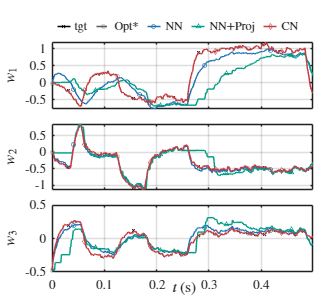

[ca_plot_] saved: Figures\sim_CA.pdf and Figures\sim_CA.eps


figure(1);
packP = struct(); [packP.export_eps, packP.export_name, packP.outdir] = deal(true, 'sim_CA', 'Figures');
ca_plot_(out, packP);

%% ===================== SAVE WORKSPACE VARIABLES (NO REBUILD) =====================
save_dir = 'C:\Users\12775\Box\jliao\m-certified-net';
if ~exist(save_dir,'dir'), mkdir(save_dir); end
stamp = datestr(now,'yyyy-mm-dd_HHMMSS');
save_path = fullfile(save_dir, ['CA_vars_' stamp '.mat']);

vars = { ...
    'nu','nw','B','G','S','h','I','u_min','u_max','du_max', ...
    'cfg_cert','OPCert','OPCertNet', ...
    'OPbase','OPNNProj','OPpureNNAlg', ...
    'Ntrain','pSwitch','alpha','sig','XTrain','YTrain','muX','sigX', ...
    'nTest','Ustar','WDtest','x0','Ts_us', ...
    'out','Rep','packP' ...
};

try
    save(save_path, vars{:}, '-v7.3');
    fprintf('[SAVE] wrote: %s\n', save_path);
catch ME
    fprintf(2,'[SAVE] FAILED: %s\n', ME.message);
    fprintf(2,'[SAVE] If file is too large, try removing XTrain/YTrain or out.\n');
end

[SAVE] wrote: C:\Users\12775\Box\jliao\m-certified-net\CA_vars_2026-02-20_104948.mat
